# **LSM710 Simulated Confocal: Laser Study**

#### **Here, we will model the Zeis LSM710 confocal microscope, studying how laser power can be modified to change the overall FOM.**

In particular, we will show a model setup where alexa 488, 568, and 647 are imaged using the 488/561/647 MBS that come standard with the Zeiss 710.

#### Model Components: 

- Fluorescence Filters: 488/561/647 MBS

- Lasers:  Argon, (488 nm, 25mW) | HeNe (561 nm, 20mW) | HeNe2 (633 nm, 5mW).

- Detectors: 34 channels, 9.8nm wide

- Fluorophore spectra (ThermoFisher) (Alexa 488, 567, 647)

**Importing features**

%I first downloaded a 488/561/647 MBS excel sheet from ? (long time ago)

**Filter**

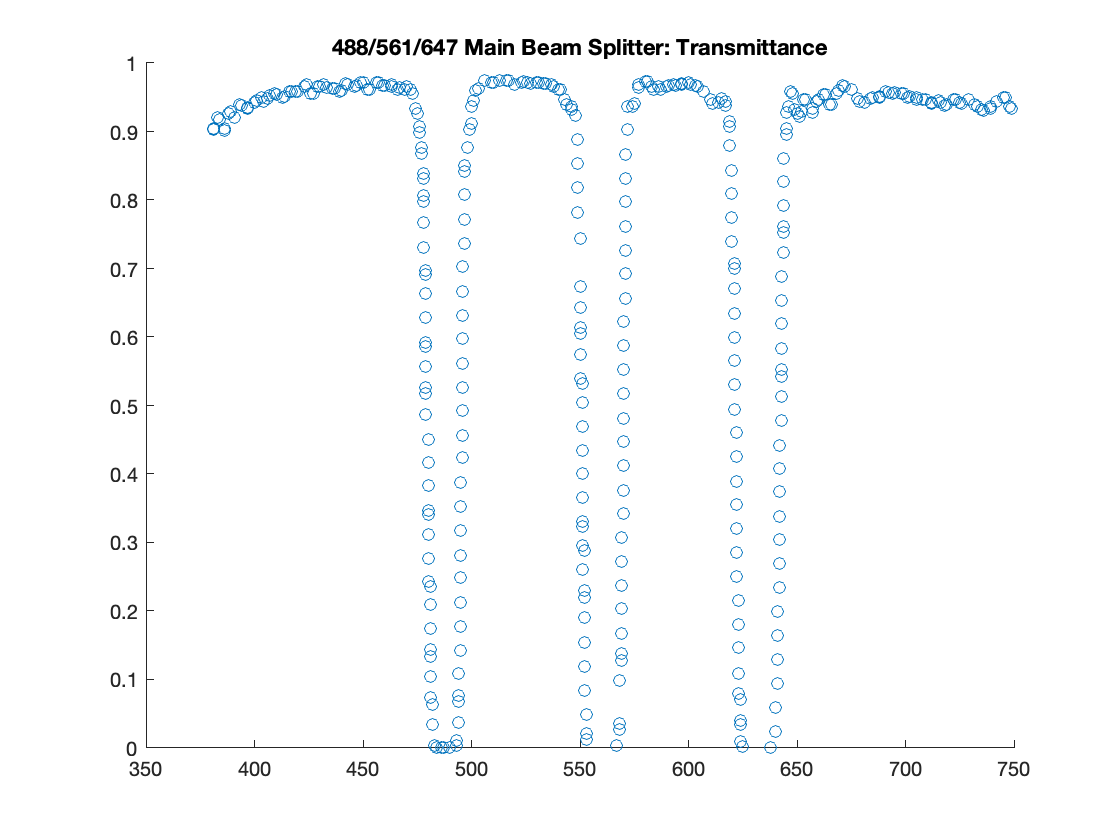

filterSpectra = readmatrix('/assets/MBSZeiss.csv'); %import filter spectra into matrix

%VISUAL:
scatter(filterSpectra(:,1), filterSpectra(:,2)) 
title("488/561/647 Main Beam Splitter: Transmittance")
ylim([0 1])

**Lasers**

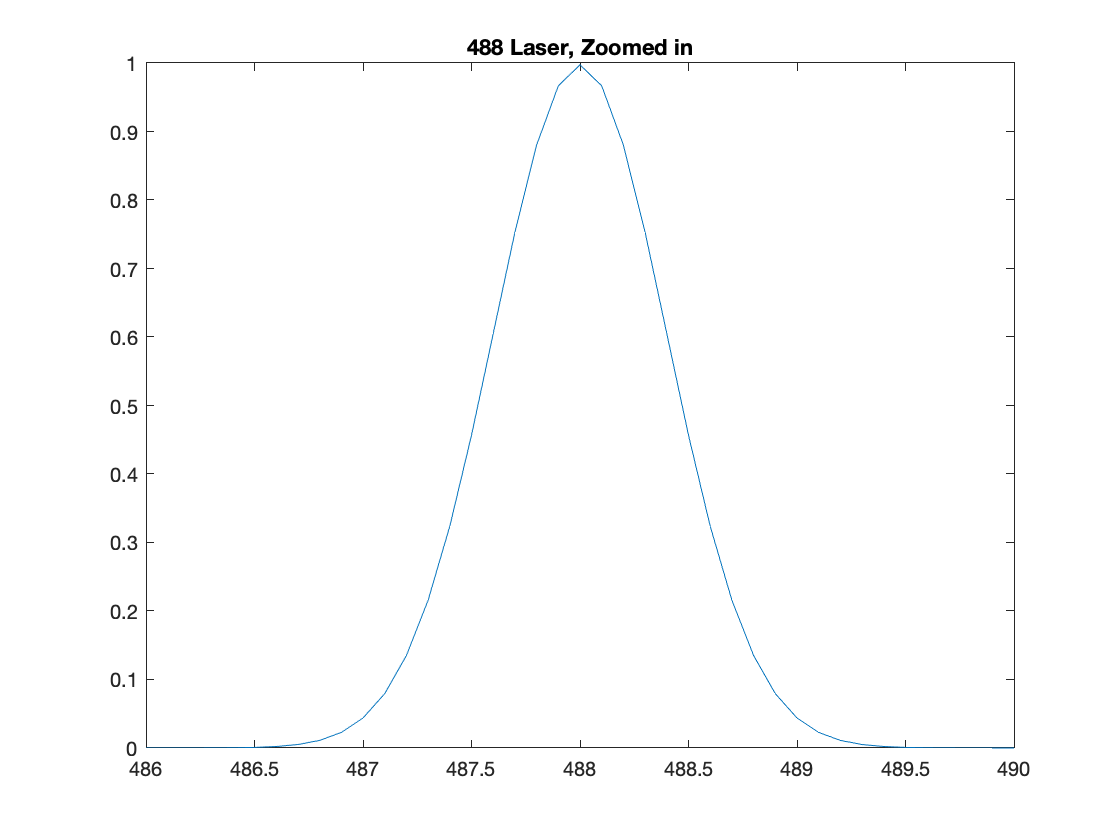

%let's generate these lasers:

wavelengths = [488 561 633]; %What lasers do we want to use?


lasers = makeLaser(wavelengths); %this function can found as "makeLaser.m" in functions

%what do the lasers look like?
%488 laser looks like:
plot(lasers(:,1,1),lasers(:,2,1))
title('488 Laser, Zoomed in')

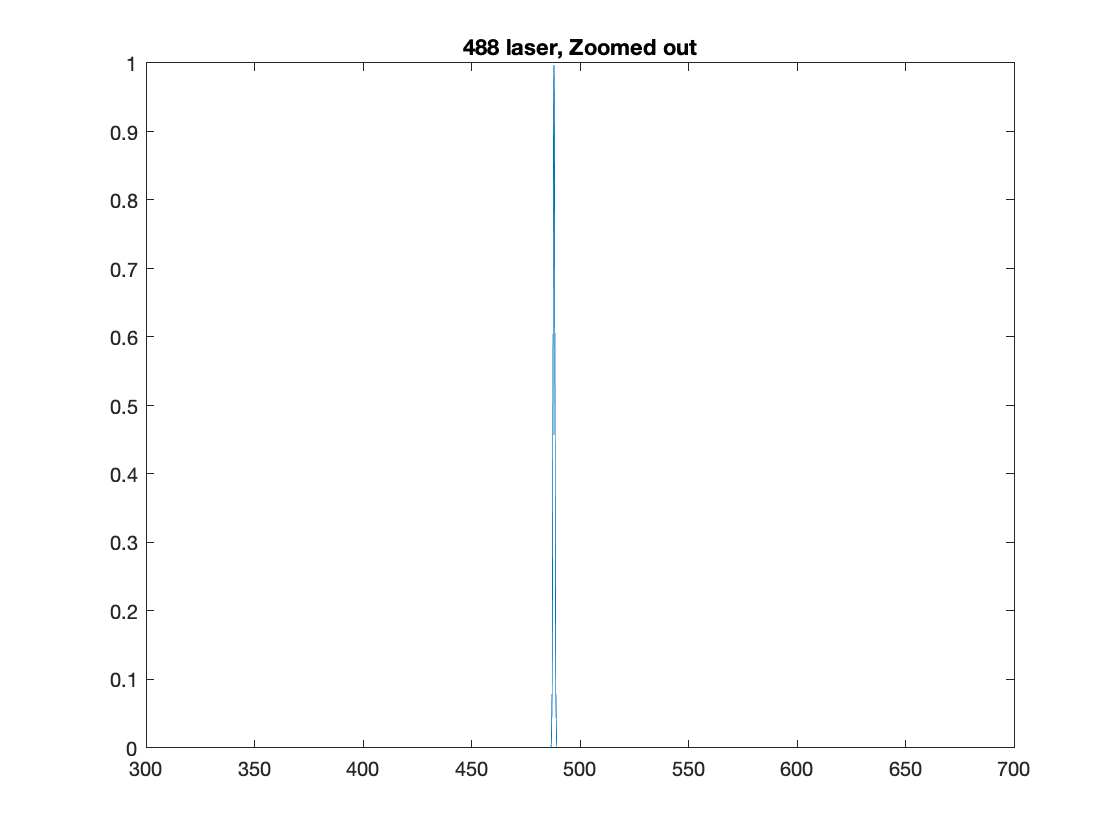



plot(lasers(:,1,1),lasers(:,2,1)) %this is the same laser as before
xlim([300 700])                    %just changed the x-range to zoom out.
title('488 laser, Zoomed out')

**Detector**

%The detector is just modeled as a 34 channel, 9.8nm wide array. This will
%become more clear later.

detector = 400:9.8:733.2;

%here, 400 is the beginning of channel 1, and 733.2 is the end of channel
%34


**Fluorophores**

%let's iterate through assets and collect our fluorophores

d = dir("assets/Alexa*"); %this pulls all the filenames with "alexa" into a struct

fluors = struct;% I'm going to put my fluorophores in a structure

for k = 1:length(d)                            %iterate through all the alexa fluors I have
    fluors(k).('name') = d(k).name;             %store their name in a structure
    fluors(k).('Spectra') = readmatrix(d(k).name); %then store their spectra in the stucture
end

fluors

fluors = 1×3 struct array with fields:
    name
    Spectra


**All our components are collected**